**Computer Exercise 3.2.18**

This program will solve the equation$2x(1+x^2)^{-1} = arctan(x)$ by approximating the positive root of $f(x) = 2x(1+x^2)^{-1} - arctan(x)$ with the bisection method. This root approximation will then be used as the initial point in using Newton's method to find the root of $f(x) =  arctan(x)$.

The program will terminate when either the number of iterates exceeds 50 for the Bisection method and 7 for Newton's method or when the following error condition is met: $| x_{n} - x_{n-1} | < \frac{1}{2} \times 10^{-5}$ 

Iterate number, corresponding x value, and the the function at x will be displayed.

f = @(x) ((2.*x).*((1 + x.^2).^(-1))) - atan(x);

We need a good idea of where to pick our starting points for the bisection method. The function is plotted out to assist in doing so.

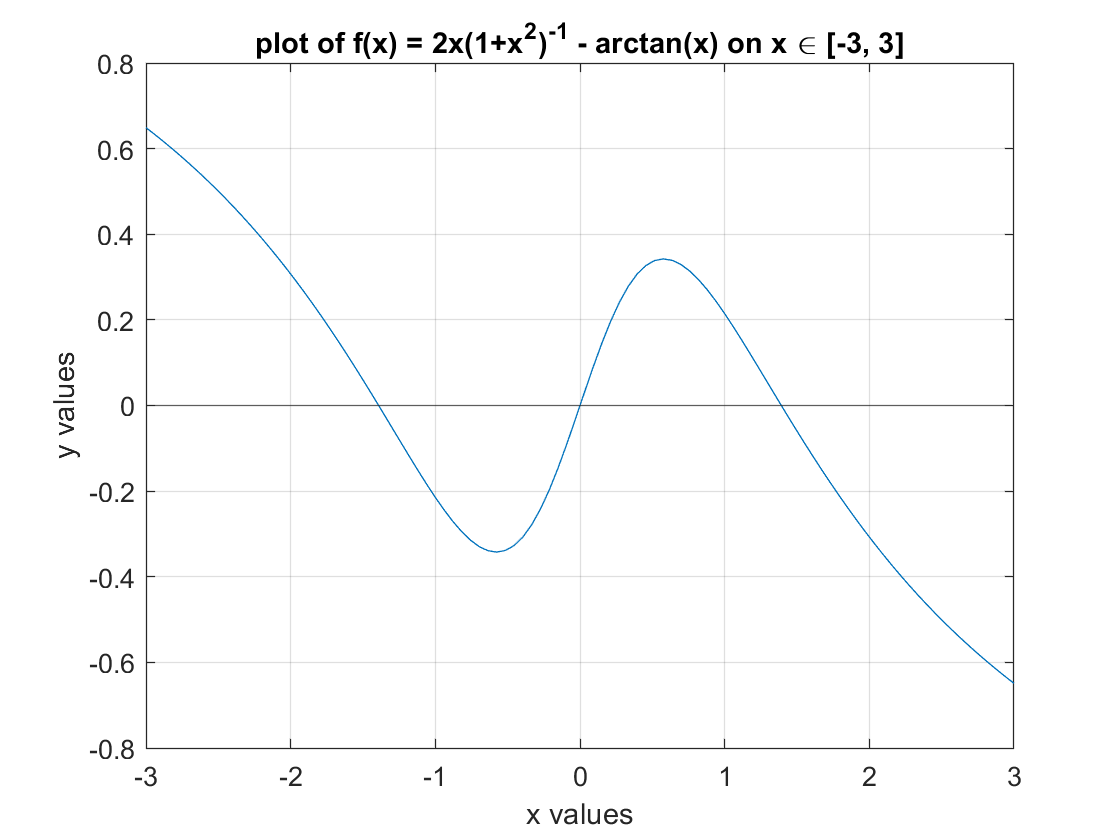

xvals = linspace(-3,3);
yvals = f(xvals);

plot(xvals, yvals)
yline(0)
title('plot of f(x) = 2x(1+x^2)^{-1} - arctan(x) on x \in [-3, 3]')
xlabel('x values')
ylabel('y values')
grid on

Based on the plot, the positive root is somewhere between x=1 and x=2 so those look like good starting points for the bisection method.

a=1;
b=2;
n=50;
error = 0.5 * 10^(-5);


root0 = bisect(f, a, b, n, error);

fprintf('root = %8.8f', root0)

root = 1.39175415

This is the value that will act as the initial starting point for Newton's method.

syms x; %program is modified to only take a function
        %as input by having the derivative evaluated
        %within the Newton algorithm; to accomplish this
        %symbolic functions are utilized

%%inputs for Newton's method        

f = atan(x); %symbolic function

x0=root0; %initial point set as the positive root from the
          %bisection method

N=7; %max number of iterates

err = 0.5 * 10^(-5); %error tolerance for successive points

m=1; %if root multiplicity is known ahead of time,
     %this value can be changed to account for
     %root multiplicity and use the modified
     %Newton's method

root1 = newton(f, x0, N, err, m);

n = 0, xn =   1.391754150391, f(xn) = 9.477501809191e-01, error = 1.000000000000e+00 
n = 1, xn =  -1.391768811204, f(xn) = -9.477551726839e-01, error = 2.783522961595e+00 
n = 2, xn =   1.391807487769, f(xn) = 9.477683410827e-01, error = 2.783576298973e+00 
n = 3, xn =  -1.391909523013, f(xn) = -9.478030792036e-01, error = 2.783717010782e+00 
n = 4, xn =   1.392178729453, f(xn) = 9.478947150013e-01, error = 2.784088252466e+00 
n = 5, xn =  -1.392889136981, f(xn) = -9.481364200390e-01, error = 2.785067866434e+00 
n = 6, xn =   1.394764817280, f(xn) = 9.487738096523e-01, error = 2.787653954261e+00 
n = 7, xn =  -1.399724050556, f(xn) = -9.504536024798e-01, error = 2.794488867836e+00 


I actually tried 10 iterates of Newton's method at first (which was really slow) but from what can be seen here, this convergence is quite.. well...garbage. I tried looking at the derivative of $f(x) =  arctan(x)$, but there is no multiplicity in the root (in fact, there is no root for the derivative). I just copied and pasted this algorithm for Newton's method from the previous problem and it worked fine there. To make sure that it was not my algorithm that was the issue, I attempted Newton's method (somewhat) manually using a calculator (keying in each iterate) and I still end up getting similar results. The root should end up being zero since $tan(0) = 0$, and after seven iterates of Newton's method, the error has not even manage to dip even below one. It turns out that the only explanation (that I can think of) for this terrible convergence is that we have a bad starting point.

function c=bisect(f, a, b, n, error) %Bisection algorithm
c=(a+b)/2;
i=1; %set iteration counter
%error = |f(c) - 0|
    while (abs(f(c))>error) && (i<=n) %exit while loop once error tolerance
       %  or max iterations has been reached
        if f(a)*f(c)<0
            b=c;
        else
            a=c;
        end
        c=(a+b)/2;
        i = i+1; %update iteration counter
    end
    if (abs(f(c))>error) %if this triggers, this means that max iterations
       %  has been reached before error tolerance
        fprintf(['bisection algorithm was unsucessful after %d iterations; ' ...
            'error = %f'], i-1, abs(f(c)))
    end
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function root = newton(f, x0, N, err, m) %Newton Algorithm
    n=0; %initialize iterate 
    syms x; %symbols needs to be redeclared otherwise
            %algorithm yields an error
   
    fd = diff(f); %symbolically evaluate derivative of
                  %input function
    
    y = subs(f, x, x0); %evaluate input function at x0
    
    dy = subs(fd, x, x0); %evaluate derivative at x0
    
    xn = x0; %initialize iterate x value for loop
    
    error = 1; %initialize error to any value such that error < err
    
    fprintf(['n = %d, xn = %16.12f, f(xn) = %16.12e, ' ...
        'error = %16.12e \n'], n, xn, y, error)
    %display the zeroth iterate
    while (error > err) && (n < N)            
        root = xn - ((m*y)/dy); %evaluate subsequent point 
                                %using Newton's method formula
        y = subs(f, x, root);        
        dy = subs(fd, x, root);        
        error = abs(xn -root); %error value between successive points        
        xn = root;        
        n = n + 1; %increment iteration number     
        fprintf(['n = %d, xn = %16.12f, f(xn) = %16.12e, ' ...
            'error = %16.12e \n'], n, xn, y, error)
        %display nth iterate
    end
end